# Gyakorlat 1

load carsmall;
% cars = importdata('carsmall.mat')

Mi az átlag, szórás és medián a Gyorsulásnál (Acceleration)?

mean(Acceleration)

ans = 15.0280

std(Acceleration)

ans = 3.3485

median(Acceleration)

ans = 15.1500

%quantile(Acceleration, .5)

Az MPG (Miles Per Gallon) fogyasztás segítségével számoljuk ki az LPHKM (L/100km) változót, ha

- 1 gallon = 3.79 liter

- 1 mérföld = 1.61 km

Az elemenkénti operációk:

LPHKM = 1./(MPG * 1.61 / 3.79)*100;

Kerekítsük 1 tizedesjegyre:

LPKHM = round(LPHKM,1);

Melyik járműnek legnagyobb a fogyasztása? Használja a 'Model' karakter tömböt a típus megtalálásához.

ind = find(LPKHM == max(LPKHM));
Model(ind,:)

ans = 'ih 1200d                         '

Hány kocsi fogyaszt többet 15 liternél? Mi az aránya ezeknek a kocsiknak?

sum(LPKHM > 15)

ans = 20

sum(LPKHM > 15) / length(LPKHM)

ans = 0.2000

Vizsgálja meg a fogyasztást grafikusan hengerek száma (Cylinders) szerint boxplot segítségével.

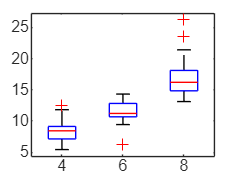

boxplot(LPKHM, Cylinders)

Ábrázolja a gyorsulás (Acceleration) értékeit hisztogrammon. Vizsgáljuk meg normalitás szempontjából.

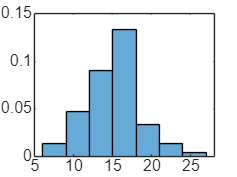

histogram(Acceleration,'Normalization','pdf')

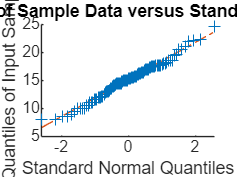

qqplot(Acceleration)

Rajzolja rá a sűrűségfüggvényt az ábrára! (**dfittool**)

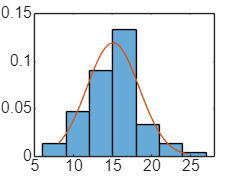

[pm pd] = normfit(Acceleration); % parameter estimations of the mean and std
xx = linspace(min(Acceleration),max(Acceleration));
histogram(Acceleration,'Normalization','pdf')
hold on;
plot(xx, normpdf(xx,pm,pd))
hold off;

Ábrázolja az empirikus eloszlásfüggvényt (ecdf) a súly (Weight) logaritmusára. Illesszünk egy megfelelőnek tűnő elméleti eloszlást az ábrára.

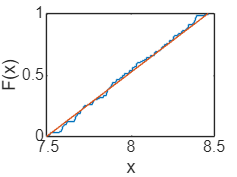

ecdf(log(Weight))
[a b] = unifit(log(Weight));
xx = linspace(a, b);
hold on;
plot(xx, unifcdf(xx,a,b))
hold off;

Az autók származási országáról (Origin) készítsen egy gyakorisági táblázatot.

tbl = tabulate(Origin);
t = cell2table(tbl,'VariableNames', ...
    {'Value','Count','Percent'});
t.Value = categorical(t.Value)

t = 6×3 table
     Value     Count    Percent
    _______    _____    _______

    USA         69        69   
    France       4         4   
    Japan       15        15   
    Germany      9         9   
    Sweden       2         2   
    Italy        1         1   


Ábrázoljuk oszlopdiagrammon.

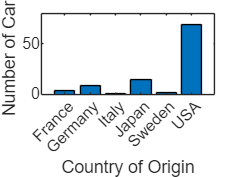

bar(t.Value,t.Count)
xlabel('Country of Origin')
ylabel('Number of Cars')